# Ergodicity and Estimation in the Time Domain

## 1. Estimation of auto- and inter-correlation functions

**The interference formula for **$K_{\mathrm{xy}}$: Given a filter with impulse response of $h\left(n\right)$, an input $X$ and the output $Y$, we have the following relationship to calculate $K_{\mathrm{XY}}$:


$$K_{\mathrm{XY}} \left(\tau \right)=\left(h*K_X \right)\left(n\right)=\sum_{m=0}^L h\left(m\right)K_X \left(n-m-\tau \right)$$


For different values of $\tau \in Z$, we have the following matrix system:


$$\left\lbrack \begin{array}{cccc}
K_x \left(n-0\right) & K_x \left(n-1\right) & \dots  & K_x \left(n-\left(L-1\right)\right)\\
\vdots  & \ddots  &  & \vdots \\
\vdots  &  & \ddots  & \vdots \\
K_x \left(n-\left(L-1\right)\right) & \dots  & \dots  & K_x \left(n-0\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
h\left(0\right)\\
\vdots \\
\vdots \\
h\left(L-1\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
K_{\mathrm{XY}} \left(0\right)\\
\vdots \\
\vdots \\
K_{\mathrm{XY}} \left(L-1\right)
\end{array}\right\rbrack$$


**Method of moments for estimating the impulse response of an RIF Filter**

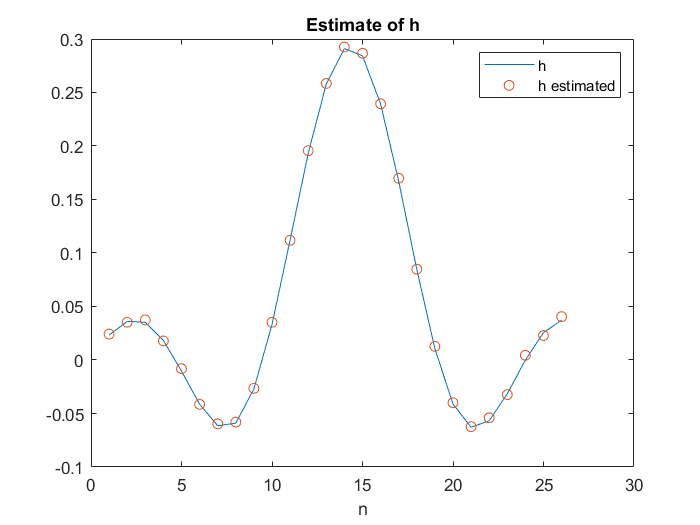

h = sin((-16:1.2:15)*(pi/5.8))./(-16:1.2:15)*(pi/5.8);
L = length(h);
num = [0.3 0.4 -0.2 0.1];
den = [1 -0.8 0.5];
X_predict = filter(num, den, randn(1,300));
Y = filter(h,1,X_predict);
nb = 300;
N = nb-L; %number of useful data

% les covariances
kX_hist = xcov(X_predict);
kYX = xcov(Y,X_predict);

r = kYX(L+1:N+L)';

R=zeros(N,L);
for i=1:N
    for j=1:L
        R(i,j)=kX_hist(L+i-(j-1));
    end
end
h_dash=(R'*R)\(R'*r);

% Comparaison par rapport au veritable h

figure
plot(h)
hold on
plot(h_dash, 'o')
legend('h','h estimated')
title('Estimate of h')
xlabel('n')

## 2. Application of the autocorrelation function

We have the trajectory of a body saved in `mouvement.mat`. Below, we see that the covaraince of the trajectory is similar to a dirac function. This justifies the use of a guassian preocess centered at 0 to model the signal.

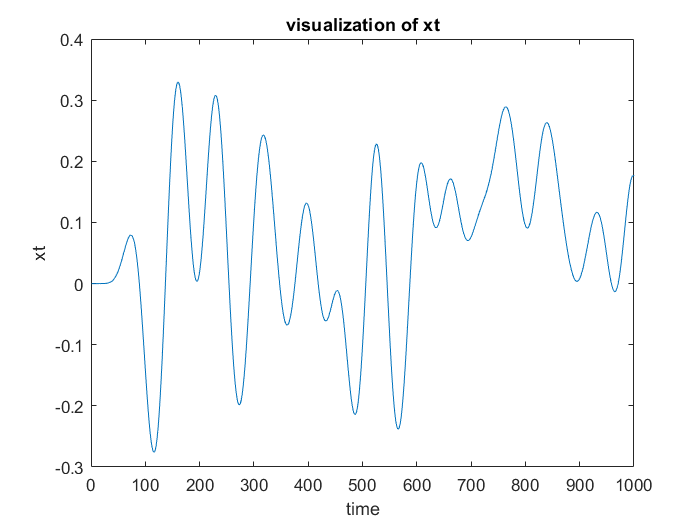

load('mouvement.mat')
load('mouvement_historique.mat')
figure
plot(xt)
title('visualization of xt')
xlabel('time')
ylabel('xt')

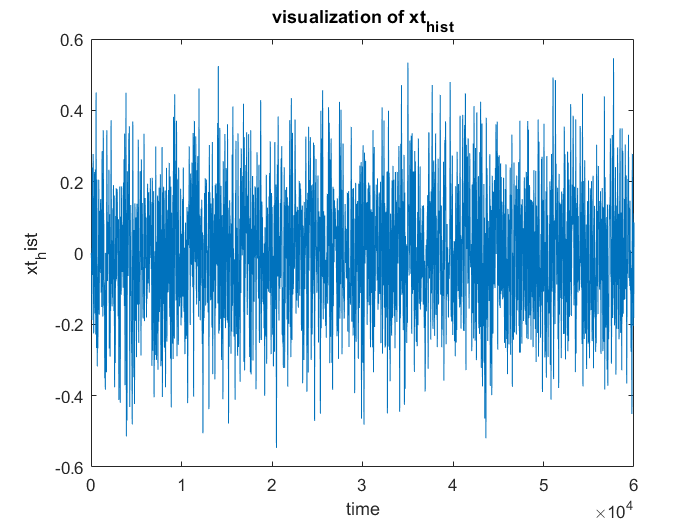

figure
plot(xt_hist)
title('visualization of xt_h_i_s_t')
xlabel('time')
ylabel('xt_hist')

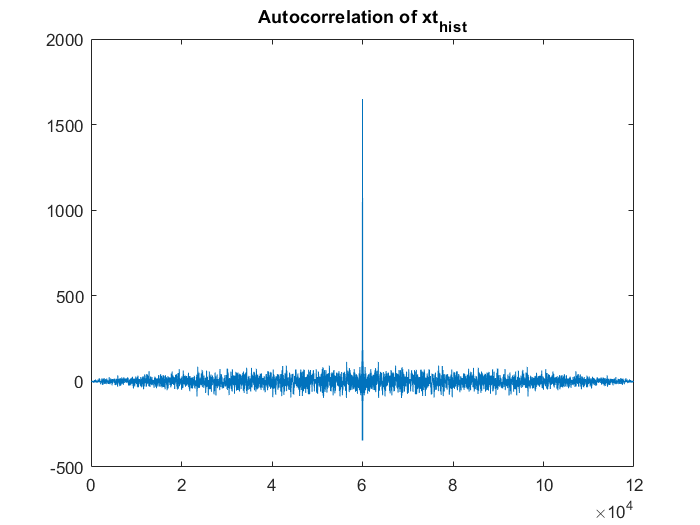

rx_hist = xcorr(xt_hist);
L= length(xt_hist);
figure
plot(rx_hist)
title('Autocorrelation of xt_h_i_s_t')

We can use the historic trajectory to get a linear multivariate model to estimate the future trajectory. Therefore, we have:


$$\hat{X_t } =\sum_{i=1}^n a_{t,i} X_i \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;,t>n$$


The $\hat{X_t }$ that minimizes the mean squared error is the projection of $X_t$ on the plane generated by the vectorial space formed by $\left\lbrace X_1 ,X_2 ,\dots ,X_n \right\rbrace$. Hence,


$$\left(X_t -\hat{X_t } \right)X_l^T =0,\;\;\;\;\;\;\;\;\;\;l\in \left\lbrack 1,n\right\rbrack$$



$$\Rightarrow \left\lbrack \left(X_t -\hat{X_t } \right)X_l^T \right\rbrack =0$$



$$\Rightarrow \left\lbrack X_t^T X_l \right\rbrack -E\left\lbrack \hat{X_t^T } X_l \right\rbrack =0$$



$$\Rightarrow K_X \left(t,l\right)-\sum_{i=1}^n a_{t,i} E\left\lbrack X_i^T X_l \right\rbrack =0$$



$$\Rightarrow K_X \left(t,l\right)-\sum_{i=1}^n a_{t,i} K_X \left(i,l\right)=0$$


Again, writing this in the form of a matrix,


$$\left\lbrack \begin{array}{cccc}
K_X \left(1,1\right) & K_X \left(2,1\right) & \dots  & K_X \left(n,1\right)\\
\vdots  & \ddots  &  & \vdots \\
\vdots  &  & \ddots  & \vdots \\
K_X \left(1,n\right) & \dots  & \dots  & K_X \left(n,n\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_{\mathrm{t1}} \\
\vdots \\
\vdots \\
a_{\mathrm{tn}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
K_X \left(t,1\right)\\
\vdots \\
\vdots \\
K_X \left(t,n\right)
\end{array}\right\rbrack$$


Below, we use the values in `mouvement.mat`. Out of the 400 values, the first 300 values are used to predict the next 100 values. 

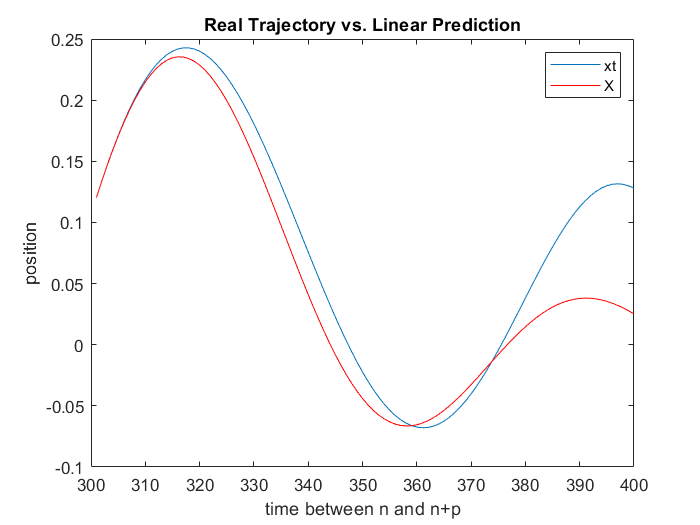

n=300;
p=100; 
t=n+p;

X_predict=zeros(1,t);
for i=1:n
    X_predict(i)=xt(i);
end 

K=zeros(n,n);
for i=1:n
    for j=1:n
        K(i,j)= rx_hist(L+j-i);
    end
end

kt=zeros(n,p);
for t=n+1:t
    for j=1:n
        kt(j,t-n)=rx_hist(L+t-j);
    end
end

at = K\kt;
X_predict(n+1:n+p)=X_predict(1:n)*at;

figure;
plot(n+1:t,xt(n+1:t))
hold on;
plot(n+1:t,X_predict(n+1:t), 'r')
legend('xt','X')
title('Real Trajectory vs. Linear Prediction')
xlabel('time between n and n+p')
ylabel('position')

We see that the predictio is pretty accurate for around the first 20 values. After that, the error begins to become significant.

## 3. Applying the Levinson Algorithm

For the mathematical details, look at the [Levinson Recursion Wikipedia](https://en.wikipedia.org/wiki/Levinson_recursion) article.

% Processus MA
sigma2 = 1;
N = 100;
e = wgn(N+2,1,sigma2);
X = zeros(N,1); 
b1 = 1;
b2 = 1;
X(1) = e(1);
X(2) = e(1) + e(2);
for i = 3:N
    X(i) = e(i-2) + e(i-1) + e(i);
end

% Prediction de trajectoire
rX = xcorr(X);
p_max = 4; %nb de valeurs utilises par la prediction + 1
k = 60; %instant a partir de lequel on predit
h = zeros(p_max);
EQM = zeros(p_max, 1);
Xdash = ones(p_max, 1);
h(1,1) = rX(N+1)/rX(N) ;
Xdash(1) = h(1,1)*X(k-1);
EQM(1) = rX(N) - rX(N+1)*h(1,1);
alpha = zeros(p_max,1);

for p=1:p_max-1   
   Coeff_p = h(p,1:p);
   Coeff_p_tilde = flip(Coeff_p);
   
   Vect_p = rX(N:N+p-1);
   Vect_p_tilde = flip(Vect_p);
   
   alpha(p) = rX(N+p+1) - Coeff_p*Vect_p_tilde;
   
   EQM(p+1) = EQM(p) -(alpha(p)^2)/EQM(p);
   h(p+1,1:p+1) = [squeeze(-Coeff_p +((alpha(p)^2)/EQM(p))*Coeff_p_tilde) -(alpha(p)^2)/EQM(p)]; %Formule de recurrence de Coeffp+1
   Xdash(p+1) = h(p+1,1:p+1)*X(k-1:-1:k-p-1);
end

X(k)

ans = 0.5283

Xdash

Xdash = 	1.0e+22 *

    0.0000
   -0.0000
   -0.0000
    7.1944


EQM

EQM = 	1.0e+14 *

    0.0000
    0.0000
   -0.0000
    1.2881
